clc; clear; addpath z_toolbox;
addpath E:\IEDpropagation\z_toolbox\Violinplot;
Path = 'step3_IEDtravelingWave';
load(fullfile(Path, 'IEDtw_ED-vs-delay_rate-vs-delay_diff-TD_diff-IL_fitting.mat'));
TD = 5:0.2:9; IL = (0.5:0.1:1.5).*100;
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
colors = [ 228  26  28; 55 126 184;
         77 175  74; 152  78 163;
        255 127   0; 255 255  51;
        166  86  40; 247 129 191;
        153 153 153; 0 191 196;
          0   0   0] / 255;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
modelStr = {'exp', 'poly1', 'poly2', 'poly3', 'poly4', 'poly5', ...
    'poly6', 'poly7', 'poly8', 'poly9', 'poly10'};
ED_delay_R2_exp = ED_delay_fit.R2adj_exp;
for nTD = 1:length(TD)
    A = squeeze(ED_delay_R2_exp(:, :, nTD));
    A(A<0) = [];
    ED_delay_R2_diffTD_mean(nTD, 1) = mean(A(:));
end
ED_delay_R2_poly = ED_delay_fit.R2adj_poly;
for n = 1:10
    for nTD = 1:length(TD)
        A = squeeze(ED_delay_R2_poly(:, :, nTD, n));
        A(A < 0) = [];
        ED_delay_R2_diffTD_mean(nTD, n + 1) = mean(A(:));
    end
end
subplot(4, 3, [1, 4]);
for n = 1:11
    plot(TD, ED_delay_R2_diffTD_mean(:, n), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', colors(n, :)); 
    hold on;
end
hold off; legend(modelStr, 'Box', 'off');
xlabel('Peak-to-Peak Threshold (std)');
ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for nIL = 1:length(IL)
    A = squeeze(ED_delay_R2_exp(:, nIL, :));
    A(A<0) = [];
    ED_delay_R2_diffIL_mean(nIL, 1) = mean(A(:));
end
for n = 1:10
    for nIL = 1:length(IL)
        A = squeeze(ED_delay_R2_poly(:, nIL, :, n));
        A(A<0) = [];
        ED_delay_R2_diffIL_mean(nIL, n + 1) = mean(A(:));
    end
end
subplot(4, 3, [2, 5]);
for n = 1:11
    plot(IL, ED_delay_R2_diffIL_mean(:, n), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', colors(n, :)); 
    hold on;
end
hold off;
legend(modelStr, 'Box', 'off');
xlabel('Time Threshold (ms)');
ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(4, 3, 3);
rate_delay_r = rate_delay_corr.r;
rate_delay_r_mean = squeeze(mean(rate_delay_r, 1));
imagesc(rate_delay_r_mean);
xticks(1:2:size(rate_delay_r_mean, 2));
xticklabels(TD(1:2:end));
yticks(1:2:size(rate_delay_r_mean, 1));
yticklabels(IL(1:2:end));
xlabel('Peak-to-Peak Threshold (std)');
ylabel('Time Threshold (ms)');
colorbar; colormap turbo;
set(gca, 'YDir', 'normal', 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(4, 3, 6);
load(fullfile('step3_IEDtravelingWave', 'IEDtw_fibN-vs-delay_diff-TD_diff-IL_fitting.mat'));
fibN_delay_r = fibN_delay_corr.r;
fibN_delay_r(fibN_delay_r == 0) = nan;
fib_delay_r_mean = squeeze(mean(fibN_delay_r, 1, 'omitnan'));
imagesc(fib_delay_r_mean);
xticks(1:2:size(fib_delay_r_mean, 2));
xticklabels(TD(1:2:end));
yticks(1:2:size(fib_delay_r_mean, 1));
yticklabels(IL(1:2:end));
xlabel('Peak-to-Peak Threshold (std)');
ylabel('Time Threshold (ms)');
colorbar; colormap turbo;
set(gca, 'YDir', 'normal', 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ax = subplot(4, 3, 7);
ED_delay_AIC_diffModel(:, 1) = ED_delay_fit.AIC_exp(:, 6, 6);
ED_delay_AIC_diffModel(:, 2:11) = squeeze(ED_delay_fit.AIC_poly(:, 6, 6, :));
x = 1:size(ED_delay_AIC_diffModel, 2);
plot(x, mean(ED_delay_AIC_diffModel, 1), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', [1, 0, 0]); 
ylabel('AIC'); ax.XColor = 'none';
xlim([0.5, 11.5]);
set(gca, 'XTick', [], 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(4, 3, 10);
ED_delay_BIC_diffModel(:, 1) = ED_delay_fit.BIC_exp(:, 6, 6);
ED_delay_BIC_diffModel(:, 2:11) = squeeze(ED_delay_fit.BIC_poly(:, 6, 6, :));
x = 1:size(ED_delay_BIC_diffModel, 2);
plot(x, mean(ED_delay_BIC_diffModel, 1), ...
        'LineStyle', '-', 'LineWidth', 2, 'Color', [1, 0, 0]); 
xticks(x); xticklabels(modelStr);
xlabel('Model'); ylabel('BIC');
xlim([0.5, 11.5]); 
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
Path = 'step4_IEDtw_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, ...
    'op5_IEDtw_ED-vs-delay_rate-vs-delay_fitting.mat'), 'rate_delay_corr');
nS = 13;
ED = rate_delay_corr(nS).ED;
delay = rate_delay_corr(nS).delay;
rate = rate_delay_corr(nS).rate;
modelfun = @(p, x) p(1) + p(2) .* (1 - exp(-x ./ p(3)));
p1 = median(delay, 'omitnan');
p2 = (max(delay, [], 'omitnan') - min(delay, [], 'omitnan'))/2;
p3 = max(std(ED, 'omitnan'), 0.5);
beta0 = [p1; p2; p3]; alpha = 0.05;
[beta, delayRes, ~, ~] = fit_lsqcurvefit(ED, delay, modelfun, beta0, alpha);
delayRes = delayRes + beta(1) + beta(2);
[beta, rateRes, ~, ~] = fit_polyfit(ED, rate, 6, 0.05);
rateRes = rateRes + beta(end);
x  = rateRes; y = delayRes;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(['r = ', num2str(r)]); disp(['p = ', num2str(p)]);

r = -0.35512
p = 1.5081e-168


[~, ~, stats, curve] = fit_polyfit(x, y, 1, 0.05);
subplot(4, 3, 8);
f_densityScatter(x, y, 2);
hold on;
plot(curve.x, curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('log(IED Traveling-Wave Rate (n/min))'); 
ylabel('IED Traveling-Wave Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear; addpath(fullfile('z_toolbox', 'Violinplot'));
Path = 'step4_IEDtw_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, ...
    'op5_IEDtw_ED-vs-delay_rate-vs-delay_fitting.mat'), 'rate_delay_corr');
rate_delay_corr_null = load(fullfile(Path, ...
    'op7_IEDtw_null_ED-vs-delay_rate-vs-delay_fitiing.mat'), 'rate_delay_corr');
for nS = 1:47
    rTrue(nS, :) = rate_delay_corr(nS).r_rED_exp;
end
for nNull = 1:1000
    for nS = 1:47
        A = rate_delay_corr_null.rate_delay_corr{nNull};
        rNull(nS, :, nNull) = A(nS).r_rED_exp;
    end
end
rNull = mean(rNull, 3);
x = rTrue(:, 6); y = rNull(:, 6);
for n = 1:length(x)
    trueStr{n, 1} = 'Empirical';
end
for n = 1:length(y)
    nullStr{n, 1} = 'Null';
end
data = [x; y];
subplot(4, 3, 9);
Origin = [trueStr; nullStr];
vs = violinplot(data, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
[p, h, stats] = ranksum(rTrue(:, 6), rNull(:, 6), 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(rTrue(:, 6), rNull(:, 6));
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 9.3678e-06 z = -4.4313 Cliff Delta = -0.53101 df = 92


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
Path = 'step4_IEDtw_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, 'op6_IEDtw_fibN-VS-delay_fitting.mat'));
nS = 13;
ED = fibN_delay_corr(nS).ED;
delay = fibN_delay_corr(nS).delay;
fibN = fibN_delay_corr(nS).fibN;
modelfun = @(p, x) p(1) + p(2) .* (1 - exp(-x ./ p(3)));
p1 = median(delay, 'omitnan');
p2 = (max(delay, [], 'omitnan') - min(delay, [], 'omitnan'))/2;
p3 = max(std(ED, 'omitnan'), 0.5);
beta0 = [p1; p2; p3]; alpha = 0.05;
[beta, delayRes, ~, ~] = fit_lsqcurvefit(ED, delay, modelfun, beta0, alpha);
delayRes = delayRes + beta(1) + beta(2);
[beta, fibNRes, ~, ~] = fit_polyfit(ED, fibN, 6, 0.05);
fibNRes = fibNRes + beta(end);
x  = fibNRes; y = delayRes;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(['r = ', num2str(r)]); disp(['p = ', num2str(p)]);

r = -0.16006
p = 4.2731e-06


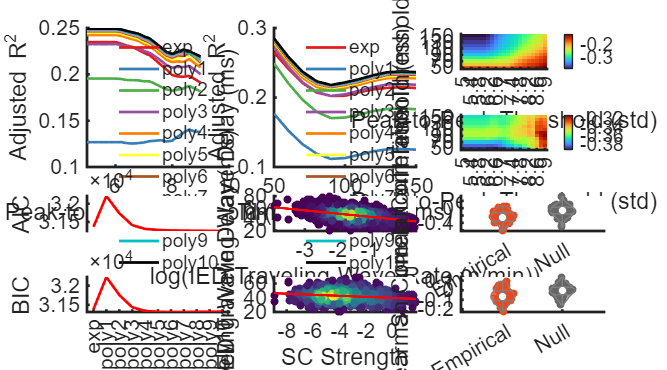

[~, ~, stats, curve] = fit_polyfit(x, y, 1, 0.05);
subplot(4, 3, 11);
f_densityScatter(x, y, 2);
hold on;
plot(curve.x, curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('IED Traveling-Wave Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
addpath(fullfile('z_toolbox', 'Violinplot'));
Path = 'step4_IEDtw_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, 'op6_IEDtw_fibN-VS-delay_fitting.mat'));
fibN_delay_corr_Null = load(fullfile(Path, 'op8_IEDtw_null_fibn-vs-delay_fitting.mat'));
N = 0;
for nS = 1:length(fibN_delay_corr)
    A = fibN_delay_corr(nS).r_rED_exp;
    if ~isempty(A)
        N = N + 1;
        rTrue(N, :) = A;
    end
end
rTrue = rTrue(:, 6);
for nNull = 1:1000
    A =  fibN_delay_corr_Null.fibN_delay_corr{nNull};
    N = 0;
    for nS = 1:length(A)
        B = A(nS).r_rED_exp;
        if ~isempty(B)
            N = N + 1;
            rNull(N, :, nNull) = B;
        end
    end
end
rNull = mean(rNull, 3);
rNull = rNull(:, 6);
x = rTrue; y = rNull;
for n = 1:length(x)
    trueStr{n, 1} = 'Empirical';
end
for n = 1:length(y)
    nullStr{n, 1} = 'Null';
end
data = [x; y];
Origin = [trueStr; nullStr];
subplot(4, 3, 12);
vs = violinplot(data, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]);
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0.007642 z = -2.6675 Cliff Delta = -0.38292 df = 64
